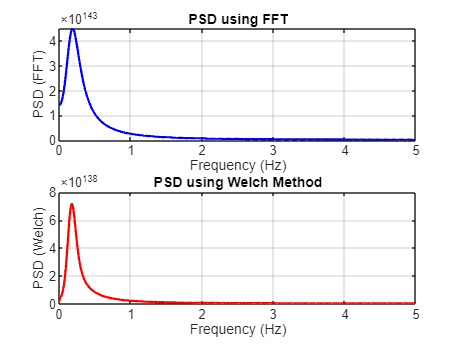

clc; clear; close all;

%% Transfer function coefficients
b = [0.02679, -0.05951, 0.01895, 0.03348, -0.01971];
a = [1, -3.952, 5.857, -3.857, 0.9523];

%% Sampling frequency
Fs = 10;  % Hz (adjust as per your system)

%% Generate impulse response (long enough for PSD)
N = 2048;   % Number of samples
imp = [1; zeros(N-1,1)];  % Unit impulse
h = filter(b, a, imp);    % Impulse response

%% Remove any NaN or Inf (safety step)
h(~isfinite(h)) = 0;

%% ---- PSD via FFT ----
H_fft = fft(h, N);
PSD_fft = (abs(H_fft).^2) / Fs;  % Power spectrum
f_fft = (0:N-1)*(Fs/N);

%% ---- PSD via Welch ----
[PSD_welch, f_welch] = pwelch(h, hamming(256), 128, 1024, Fs);

%% ---- Plot Results ----
figure;

subplot(2,1,1);
plot(f_fft(1:N/2), PSD_fft(1:N/2), 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); ylabel('PSD (FFT)');
title('PSD using FFT');
grid on;

subplot(2,1,2);
plot(f_welch, PSD_welch, 'r', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); ylabel('PSD (Welch)');
title('PSD using Welch Method');
grid on;